# Proyecto 2 Metodos

% Proyecto 2 Metodos
% Inicialización de Variables y Condiciones Iniciales
F13 = 38;
F31 = 18;
F21 = 20;
F32 = 18;
V1 = 2900;
V2 = 850;
V3 = 1180;

% Condiciones iniciales
mu1 = 0; 
mu2 = 0; 
mu3 = 0; 
mu = [mu1; mu2; mu3]; % Condiciones iniciales

% Definición de la función de entrada de contaminantes
p = @(t) 1 + sin(t);

% Definir el intervalo de tiempo para la simulación
a=0;
b=50;
h=0.1;

y1_prime = @(t, y1, y2, y3) (F13/V3) * y3 + p(t) - (F31/V1) * y1 - (F21/V1) * y1

y1_prime = function_handle with value:
    @(t,y1,y2,y3)(F13/V3)*y3+p(t)-(F31/V1)*y1-(F21/V1)*y1


y2_prime = @(t, y1, y2, y3) (F21/V1) * y1 - (F32/V2) * y2

y2_prime = function_handle with value:
    @(t,y1,y2,y3)(F21/V1)*y1-(F32/V2)*y2


y3_prime = @(t, y1, y2, y3) (F31/V1) * y1 + (F32/V2) * y2 - (F13/V3) * y3

y3_prime = function_handle with value:
    @(t,y1,y2,y3)(F31/V1)*y1+(F32/V2)*y2-(F13/V3)*y3



f = @(t, y) [
    y1_prime(t, y(1), y(2), y(3));
    y2_prime(t, y(1), y(2), y(3));
    y3_prime(t, y(1), y(2), y(3));
]

f = function_handle with value:
    @(t,y)[y1_prime(t,y(1),y(2),y(3));y2_prime(t,y(1),y(2),y(3));y3_prime(t,y(1),y(2),y(3))]


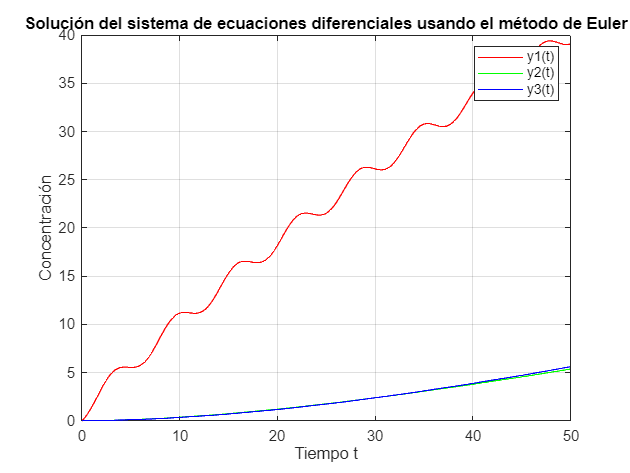


[t, y] = euler(f, a, b, mu, h);

figure;
plot(t, y(1, :), 'r', t, y(2, :), 'g', t, y(3, :), 'b');
legend('y1(t)', 'y2(t)', 'y3(t)');
xlabel('Tiempo t');
ylabel('Concentración');
title('Solución del sistema de ecuaciones diferenciales usando el método de Euler');
grid on;

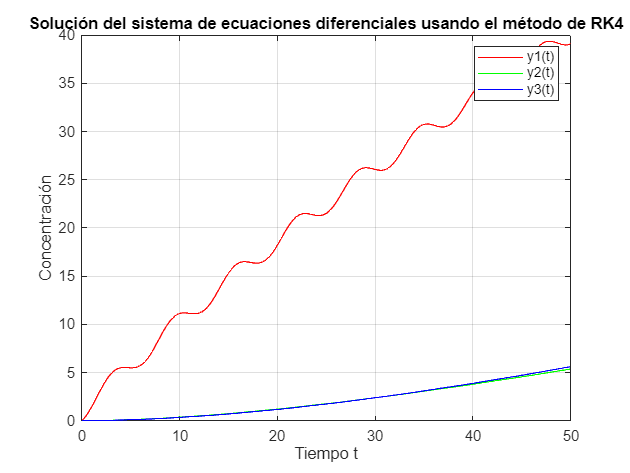



[t,y] = rk4(f, a, b, mu, h);
figure;
plot(t, y(1, :), 'r', t, y(2, :), 'g', t, y(3, :), 'b');
legend('y1(t)', 'y2(t)', 'y3(t)');
xlabel('Tiempo t');
ylabel('Concentración');
title('Solución del sistema de ecuaciones diferenciales usando el método de RK4');
grid on;

function [t, y] = euler(f, a, b, y0, h)
    t = a:h:b;                
    y = zeros(length(y0), length(t));
    y(:,1) = y0;

    for i = 1:(length(t) - 1)
        y(:,i+1) = y(:,i) + h * f(t(i), y(:,i));
    end
end

function [t, y] = rk4(f, a, b, y0, h)
    t = a:h:b;                
    y = zeros(length(y0), length(t));  
    y(:,1) = y0;

    for i = 1:(length(t) - 1)
        k1 = h * f(t(i), y(:,i));
        k2 = h * f(t(i) + h/2, y(:,i) + k1/2);
        k3 = h * f(t(i) + h/2, y(:,i) + k2/2);
        k4 = h * f(t(i) + h, y(:,i) + k3);
        
        y(:,i+1) = y(:,i) + (k1 + 2*k2 + 2*k3 + k4) / 6;
    end
end